load('data.mat');
load('illumination.mat');
load('pose.mat');


%First half: Neutral vs. Smiling Faces

%Restructuring data:

%face_neutral = face(:,:,1:3:end);
%face_exp = face(:,:,2:3:end);
%face_illum = face(:,:,3:3:end);

ks = 5:5:100;
kfacc = zeros(size(ks,2),2);


counter = 1;
  
    d = 5;
    [a1,b1,n1] = size(face);
    face2 = reshape(face,a1*b1,n1)'; %each row is an image
    face_neu2 = face2(1:3:end,:);
    face_exp2 = face2(2:3:end,:);
    labels = repmat([1;2;3],200);
        
    
    
    %splitting train/test
    rng(13);
    N = 100; %number of training examples per class
    N2 = 200-N; %number of test examples per class
    randidx = randperm(200);
    trainidx = randidx(1:N);
    testidx = randidx(N+1:end);
    
    train_x = [face_neu2(trainidx,:);face_exp2(trainidx,:)];
    train_y =[repmat(1,[N,1]);repmat(2,[N,1])];
    
    test_x = [face_neu2(testidx,:);face_exp2(testidx,:)];
    test_y = [repmat(1,[N2,1]);repmat(2,[N2,1])];
    
    %PCA
    %d=20;
    %[train_x2,V,mu_train] = myPCA(train_x,d);
    
    %calibrating PCA filter using training data:
    train_n = size(train_x,1);
    colmean = mean(train_x,1);
    train_x_center = train_x-repmat(colmean,[train_n,1]);
    [U,S,V] = svd(train_x_center);
    
    %applying PCA to training data
    train_x2 = train_x_center*V(:,1:d);
    
    %applying PCA to test data
    test_n = size(test_x,1);
    test_x2 = (test_x-repmat(colmean,[test_n,1]))*V(:,1:d); 
    
    size(train_x2);
    size(test_x2);
    
    
%     %Bayesian classifier
%     %Training
%     train_xn = train_x2(train_y==1,:);
%     train_xe = train_x2(train_y==2,:);
%     size(train_xn);
%     size(train_xe);
%     
%     N_n = size(train_xn,1);
%     N_e = size(train_xe,1);
%     mu_n = mean(train_xn,1);
%     train_xn_demean = train_xn-repmat(mu_n,[N_n,1]); %demeaned face_n to compute covariance matrix
%     var_n = train_xn_demean'*train_xn_demean/N_n;
%     
%     mu_e = mean(train_xe,1);
%     train_xe_demean = train_xe-repmat(mu_e,[N_e,1]); %demeaned face_n to compute covariance matrix
%     var_e = train_xe_demean'*train_xe_demean/N_e;
%     
%     %defining discriminant functions:
%     P_n = 0.5;
%     P_e = 1-P_n;
%     
%     d = size(train_x2,2);
%     k = 2; % number of classes to define discriminant for
%     %initializing variables for storage:
%     W = zeros(d,d,k);
%     w = zeros(d,k);
%     omega = zeros(k,1);
%     
%     %For n(neutral):
%     invar_n = inv(var_n);
%     W(:,:,1) = -0.5*invar_n;
%     w(:,1) = invar_n*mu_n';
%     omega(1) = -0.5*mu_n*invar_n*mu_n'-0.5*log(det(var_n))+log(P_n);
%     
%     
%     %For e(expression):
%     
%     invar_e = inv(var_e);
%     W(:,:,2) = -0.5*invar_e;
%     w(:,2) = invar_e*mu_e';
%     omega(2) = -0.5*mu_e*invar_e*mu_e'-0.5*log(det(var_e))+log(P_e);
%     
% %     figure; 
% %     imagesc(var_n); 
% %     colorbar; 
%     
%     %Evaluating discriminants on test data:
%     N_test = size(test_x2,1); %counting number of test observations
%     G = zeros(N_test,k); %initializing array (row = obs, col = discriminant class) 
%     
%     %g_n = @(x)x*W_n*x'+w_n'*x'+omega_n0;
%     %g_e = @(x)x*W_e*x'+w_e'*x'+omega_e0;
%     g = @(x,a)x*W(:,:,a)*x'+w(:,a)'*x'+omega(a); %defining discriminant function, with x = obs. row, a = class
%     
%     %g(test_x2(1,:),1)
%     for i = 1:N_test
%         for j = 1:k
%             G(i,j) = g(test_x2(i,:),j);
%         end
%     end
%     
%     [Z,test_y_prB]=max(G,[],2); %computing predicted y 
%     dfacc(counter,1)= mean(test_y_prB==test_y);    
    
for K = ks    
    %kNN
    %K = 20;
    l=1;
    test_y_prK = myKNN(train_x2,train_y,test_x2,K,l);
    kfacc(counter,1) = mean(test_y_prK==test_y);
    
    %kNN
    %K = 20;
    l=2;
    test_y_prK = myKNN(train_x2,train_y,test_x2,K,l);
    kfacc(counter,2 )= mean(test_y_prK==test_y);
    counter= counter+1;
end


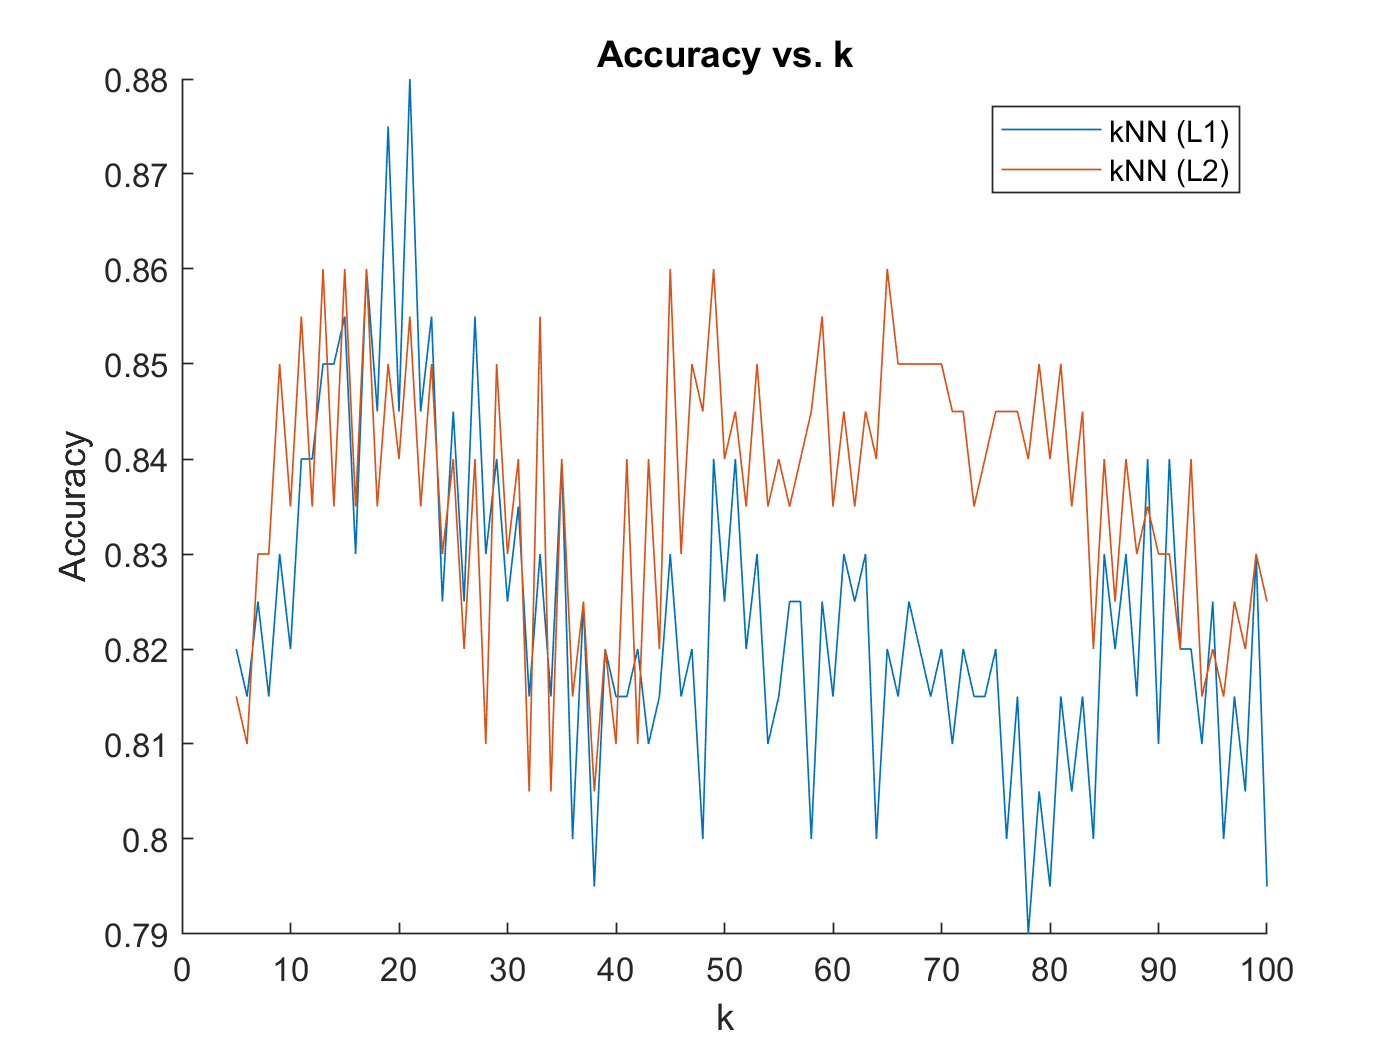

clf('reset')
%plotting results
figure(2)
hold on
PL1 = plot(ks,kfacc(:,1));
PL2 = plot(ks,kfacc(:,2));
%PL3 = plot(ds,dfacc(:,3));
%PL4 = plot(ks,kacc(:,4));
xlabel("k")
ylabel("Accuracy")
title("Accuracy vs. k")
legend([PL1,PL2], "kNN (L1)","kNN (L2)")
hold off